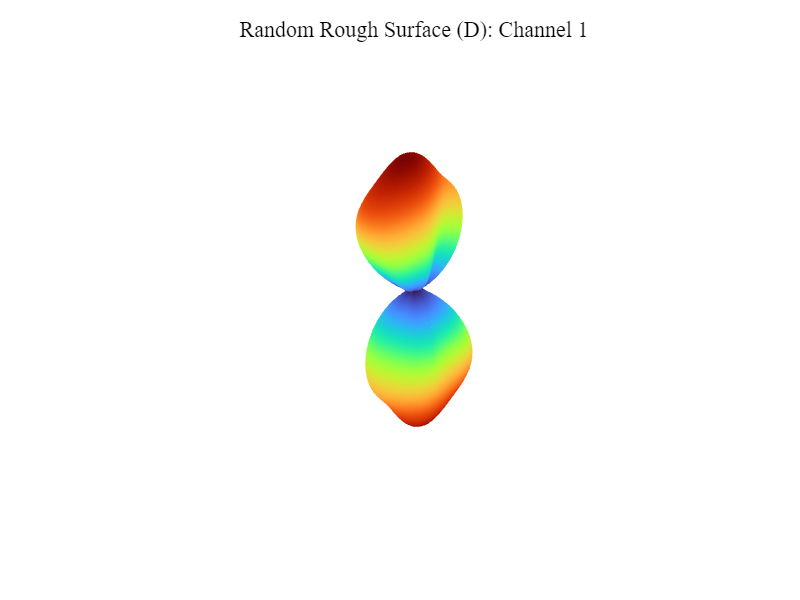

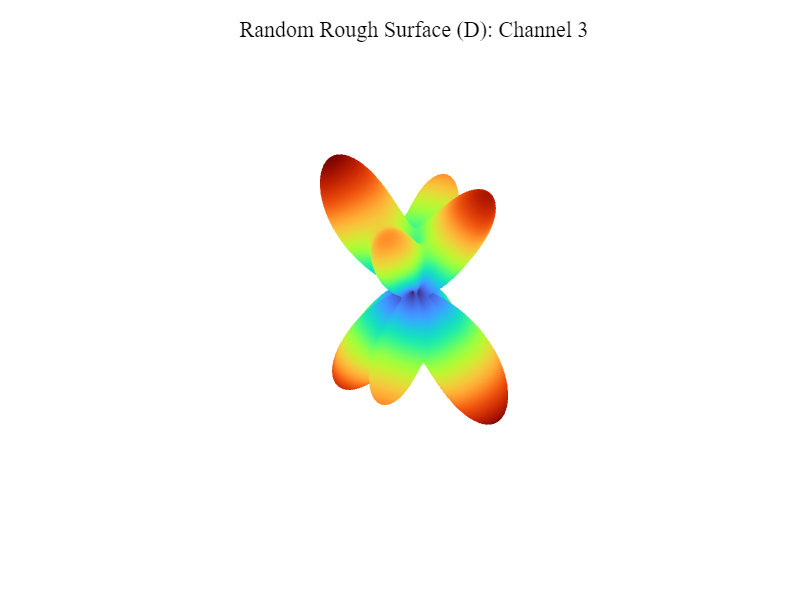

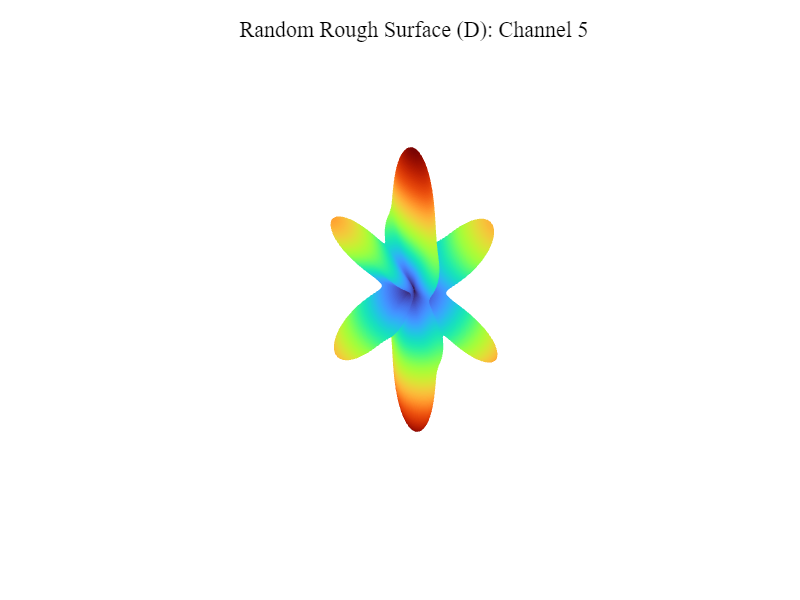

% =========================================================================
% Random Rough Surface: Eigenchannel Radiation Patterns (Lossless / PEC)
%
% This script visualizes eigenchannel radiation patterns of a random rough
% surface under the lossless condition with surface impedance Zs = 0 (PEC).
%
% Data are loaded from 'Channel_Lossless.mat'.
%
% Output:
%   - 3D radiation pattern surfaces (e.g., Directivity-like quantity)
%   - One figure per selected eigenchannel
%
% Copyright (c) 2026 Chenbo Shi, UESTC, China.
% =========================================================================

clear; close all; clc;

%% ----------------------------- User settings ---------------------------
dataFile   = 'Channel_Lossless.mat';

% Which eigenchannels to plot (must match variables in the .mat file)
% The script expects fields named rE1, rE3, rE5, ... (each Nx3 complex)
channels   = [1 3 5];

% What to visualize:
%   "D"   : Directivity-like quantity used in the original code
%   "RCS" : 4*pi*|E|^2
%   "MagE": |E|
resultType = "D";

% Plot settings
cmapName   = "turbo";
viewAng    = [16 31];
fontName   = "Times New Roman";
fontSize   = 10;

% Colorbar control (set true if you want it)
showColorbar = false;

% If you want fixed axis limits (not recommended), set fixedLim = 1, etc.
% Otherwise keep empty for auto scaling.
fixedLim = [];  % e.g., 1

%% ------------------------------ Load data ------------------------------
if ~isfile(dataFile)
    error("Data file '%s' not found in the current directory.", dataFile);
end
S = load(dataFile);

% Required variable: obs
if ~isfield(S, 'obs')
    error("Missing variable 'obs' in '%s'.", dataFile);
end

% Prepare observation angles
% obs(:,2) = theta (deg), obs(:,3) = phi (deg) in your original convention
mt = deg2rad(reshape(S.obs(:,2), 181, 181));   % theta grid
mp = deg2rad(reshape(S.obs(:,3), 181, 181));   % phi grid

%% ------------------------------ Main loop ------------------------------
for ch = channels
    field = sprintf('rE%d', ch);
    if ~isfield(S, field)
        error("Missing variable '%s' in '%s'.", field, dataFile);
    end

    rE = S.(field); % expected size: (181*181) x 3 (or compatible)

    Res = compute_result_from_rE(rE, mt, mp, resultType);

    plot_radiation_surface(Res, mt, mp, ch, resultType, cmapName, viewAng, ...
        fontName, fontSize, showColorbar, fixedLim);
end


%% ------------------------------ Functions ------------------------------
function Res = compute_result_from_rE(rE, mt, mp, resultType)
% Compute |E|, RCS, and a Directivity-like quantity from rE and obs grid.

    % |E| magnitude in observation directions
    MagE = sqrt(abs(rE(:,1)).^2 + abs(rE(:,2)).^2 + abs(rE(:,3)).^2);

    % reshape to grid
    MagE = reshape(MagE, size(mt,1), size(mt,2));

    % Basic quantities
    RCS = 4*pi * MagE.^2;

    % Original normalization logic (kept consistent with your code)
    eta = 120*pi;
    dth = pi/180;
    dph = 2*pi/180;

    % D0 ~ ∫ |E|^2 sin(theta) dOmega  (discrete form matched to your original)
    D0 = dth * dph * sum(MagE.^2, 1) * sin(mt(1,:))';
    Prad = D0 / (2*eta);
    D = RCS / Prad / (2*eta);

    % Select output
    switch string(resultType)
        case "MagE"
            Res = MagE;
        case "RCS"
            Res = RCS;
        case "D"
            Res = D;
        otherwise
            error("Unknown resultType='%s'. Use 'D', 'RCS', or 'MagE'.", resultType);
    end
end

function plot_radiation_surface(Res, mt, mp, ch, resultType, cmapName, viewAng, ...
    fontName, fontSize, showColorbar, fixedLim)
% Plot a 3D radiation surface using sph2cart.

    [x,y,z] = sph2cart(mp, pi/2 - mt, Res);

    fig = figure('Color','w');
    colormap(fig, cmapName);

    h = surf(x, y, z, Res);
    set(h, 'EdgeColor','none');

    axis equal; axis off;
    shading interp;
    view(viewAng);

    set(gca, 'FontSize', fontSize, 'FontName', fontName);

    % Adaptive axis limits to avoid "empty" plots due to clipping
    if isempty(fixedLim)
        lim = max(Res(:), [], 'omitnan');
        if ~isfinite(lim) || lim <= 0
            lim = 1;
        end
        axis([-lim lim -lim lim -lim lim]);
    else
        axis([-fixedLim fixedLim -fixedLim fixedLim -fixedLim fixedLim]);
    end

    % Optional colorbar
    if showColorbar
        bartick = floor(linspace(min(Res(:)), max(Res(:)), 5) * 100) / 100;
        colorbar('Ticks', bartick, 'FontSize', fontSize);
    end

    title(sprintf('Random Rough Surface (%s): Channel %d', resultType, ch), ...
        'FontName', fontName, 'FontSize', fontSize+1);
end
